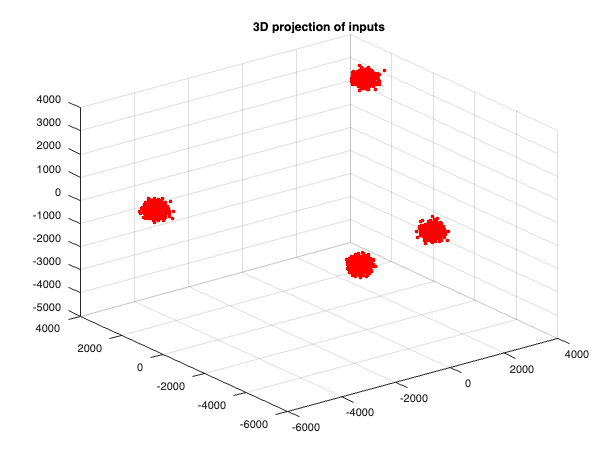

clear
format shortG
SetRNG(111);
% generate input data
k = 4;
dim = 100;
mu_range = [-1000 1000];
%mu_range = [0 2000];
sigma = 100;
split_num = 2;
[center1,mu_mat] = subcluster_centroid(k,dim,split_num,mu_range,sigma); 
means = [];

center = mu_mat;

% data generation with the given centroids
dim = 100;
num = 1000;
sigma = 150;
[inputs,c] = subcluster_simulate(center,dim,num,sigma);
data = inputs';


true_label = repelem([1:4],1000)';

% pca on input data
coeff = pca(inputs);
Z=inputs*coeff(:,1:3);
figure;hold on
view(3);
plot3(Z(:,1),Z(:,2),Z(:,3),'r.','MarkerSize',10)
title('3D projection of inputs');
%legend('inputs','layer1 centroids','layer2 centroids','layer3 centroids','Location','NW')
grid on 
hold off

% generate synaptic weights
SetRNG(111);
n_src = 100;
n_dst = 200;
n_per_src = 20;
synaptic_weights_mat = randn(n_src,n_dst)*1000;
[srcIdx,dstIdx] = ConnectHypergeometric(n_dst, n_src, n_per_src);
index = [srcIdx;dstIdx];
for i = 1:n_dst;
    nonzero_idx = index(2,find(index(1,:) == i));
    zero_idx = setdiff(1:n_src,nonzero_idx);
    synaptic_weights_mat(zero_idx,i) = 0;
end
cells = synaptic_weights_mat; %original

% cycle 1, find the cluster winners
ori_cycle1_cells = cells;
cycle1_cells = normc(cells);
cycle1_cells_iter = normc(cells);

% the dot product needs normalization while the updating does not, so we
% have cycle1_cells and cycle1_cells_iter

for k = 1:10;
    cycle1_winners = [];
    sampled_data = data(:, randperm(size(data, 2)));
    winner_len_mat = [];
    winner_average = zeros(100,1,200);
    for col = 1:size(sampled_data,2); % loop over all inputs
        lr = 0.009;
        input1 = sampled_data(:,col);% each input
        len_input = norm(input1);
        input1 = normc(input1);
        winner_per_cycle = [];
        product = input1'*cycle1_cells; % the dot products of the input and all cells
        winning_value = max(product); % max dot product value
        winning_idx = find(product == winning_value); % index(indices) of winning cell(s)
        winning_cell = cycle1_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        % loop over each winning cell in the set, in case of tied winners,
        % which may not happen
        updated_winningset = []; % in case of tied winners
        for cell_idx = winning_idx;
            winner = cycle1_cells_iter(:,cell_idx);
            cycle1_winners = [cycle1_winners;cell_idx];
            update_winner_ori = winner+(input1-winner)*lr; %update_winner_ori is NOT norm
            %new lines
            winner_average(:,:,cell_idx) = update_winner_ori + winner_average(:,:,cell_idx);

            len_update_winner = norm(update_winner_ori);
            update_winner = update_winner_ori/len_update_winner;
            updated_winningset = [updated_winningset;update_winner];
            winner_len_mat = [winner_len_mat;[cell_idx,len_input]];           
            cycle1_cells(:,cell_idx) = update_winner; 
            cycle1_cells_iter(:,cell_idx) = update_winner_ori; 
            %ori_cycle1_cells(:,cell_idx) = update_winner*len_input;
        end  
    end
end
[~,~,ix] = unique(cycle1_winners,"stable");
winner_stats = [unique(cycle1_winners,"stable"),accumarray(ix,1)];

for i = 1:size(winner_stats,1);
winner_average(:,:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1))./winner_stats(i,2);
cycle1_cells(:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1)); 
end

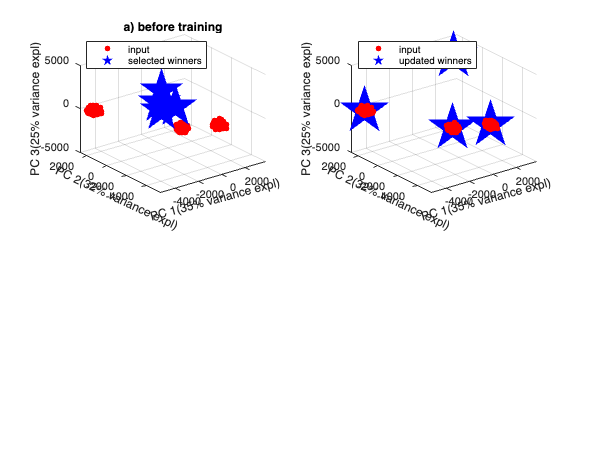


% each input wins which?
cycle1_winner=cycle1_winners;
cycle1_winners = unique(cycle1_winners,"stable");
[~,idx_1] = max(normr(inputs)*cycle1_cells(:,cycle1_winners),[],2);
cycle1_winners = cycle1_winners(unique(idx_1,"stable")); 


for c = cycle1_winners';
    each_input = winner_len_mat(winner_len_mat(:,1)== c,2);
    ori_cycle1_cells(:,c) = cycle1_cells(:,c)*mean(each_input);
end
cycle1_winner_demask = ori_cycle1_cells(:,cycle1_winners);
% cycle1_winner_demask might have more than the # of clusters; that is, some of the clusters
% may have two or more "new centroids" and they are very close. select the one
% that is closest to the designed centroids.

[~,idx]= max(mu_mat*cycle1_winner_demask,[],2);
cycle1_winners = cycle1_winners(idx); % now it's the right #
cycle1_winner_demask = ori_cycle1_cells(:,cycle1_winners);

% before cycle 1 plots
final_all_data = [inputs;cells(:,cycle1_winners)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Zb1=final_all_data*coeff(:,1:3);
explained_b = round(explained);

final_all_data = [inputs;ori_cycle1_cells(:,cycle1_winners)'];
[coeff,~,~,~,explained,~] = pca(final_all_data);
Za1=final_all_data*coeff(:,1:3);
explained_a = round(explained);

figure;
subplot(2,2,1)
hold on
view(3)
plot3(Zb1(1:length(data),1),Zb1(1:length(data),2),Zb1(1:length(data),3),'r.','MarkerSize',15)
plot3(Zb1(end-3:end,1),Zb1(end-3:end,2),Zb1(end-3:end,3),'bp','MarkerFaceColor','blue','MarkerSize',40)
title("a) before training")
legend('input','selected winners','Location','NW')
xlabel('PC 1(' + string(explained_b(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_b(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_b(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off


% after cycle 1 plots
subplot(2,2,2)
hold on
view(3)
plot3(Za1(1:length(data),1),Za1(1:length(data),2),Za1(1:length(data),3),'r.','MarkerSize',15)
plot3(Za1(end-3:end,1),Za1(end-3:end,2),Za1(end-3:end,3),'bp','MarkerFaceColor','blue','MarkerSize',45)
%plot3(Za1(end,1),Za1(end,2),Za1(end,3),'bp','MarkerFaceColor','blue','MarkerSize',10)
%title("b) after training")
legend('input','updated winners','Location','NW')
xlabel('PC 1(' + string(explained_a(1))+"% variance expl)")
ylabel('PC 2(' + string(explained_a(2))+"% variance expl)")
zlabel('PC 3(' + string(explained_a(3))+"% variance expl)")
xh = get(gca,'XLabel'); % Handle of the x label
set(xh, 'Units', 'Normalized')
pos = get(xh, 'Position');
set(xh, 'Position',pos.*[1,-0.05,1],'Rotation',15)
yh = get(gca,'YLabel'); % Handle of the y label
set(yh, 'Units', 'Normalized')
pos = get(yh, 'Position');
set(yh, 'Position',pos.*[1,-0.07,1],'Rotation',-25)
grid on
hold off

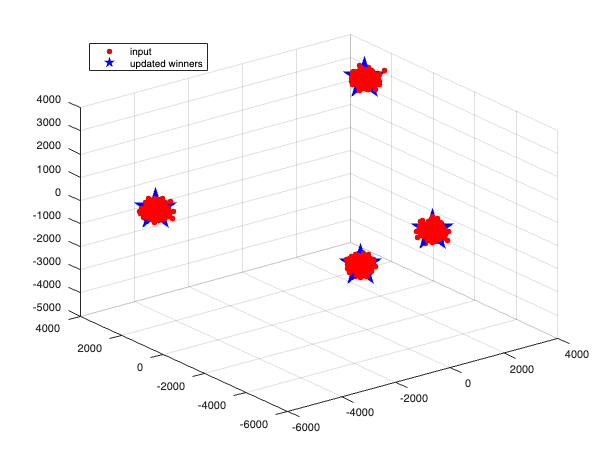


figure;
hold on
view(3)
plot3(Za1(1:length(data),1),Za1(1:length(data),2),Za1(1:length(data),3),'r.','MarkerSize',15)
plot3(Za1(end-3:end,1),Za1(end-3:end,2),Za1(end-3:end,3),'bp','MarkerFaceColor','blue','MarkerSize',40)
%plot3(Za1(end,1),Za1(end,2),Za1(end,3),'bp','MarkerFaceColor','blue','MarkerSize',10)
%title("b) after training")
legend('input','updated winners','Location','NW')
grid on
hold off




dist1= norm(mu_mat(1,:)'-ori_cycle1_cells(:,cycle1_winners(1)), 2); % c to winner
dist2= norm(mu_mat(2,:)'-ori_cycle1_cells(:,cycle1_winners(2)), 2); % c to winner
dist3= norm(mu_mat(3,:)'-ori_cycle1_cells(:,cycle1_winners(3)), 2); % c to winner
dist4= norm(mu_mat(4,:)'-ori_cycle1_cells(:,cycle1_winners(4)), 2); % c to winner
dist5= norm(mu_mat(1,:)-mu_mat(2,:), 2); % c to c
dist6= norm(mu_mat(2,:)-mu_mat(3,:), 2); % c to c
dist7= norm(mu_mat(3,:)-mu_mat(4,:), 2); % c to c
dist8= norm(mu_mat(4,:)-mu_mat(1,:), 2); % c to c

c_2_winner = [];
c_2_c = [];
id = ['A','B','C','D'];
for i = 1:4;
    c_2_winner = [c_2_winner;"centroid "+id(i) + " and winner " + id(i)];
    if i<4;
        c_2_c = [c_2_c;"centroid "+id(i) + " and centroid " + id(i+1)];
    else
        c_2_c = [c_2_c;"centroid "+id(i) + " and centroid " + id(1)];
    end
end
c_2_winner_dist = [dist1;dist2;dist3;dist4];
c_2_c_dist = [dist5;dist6;dist7;dist8];
T_cycle1 = table(c_2_winner,c_2_winner_dist,c_2_c,c_2_c_dist)

T_cycle1 = 4×4 table
           c_2_winner            c_2_winner_dist               c_2_c               c_2_c_dist
    _________________________    _______________    ___________________________    __________

    "centroid A and winner A"        45.126         "centroid A and centroid B"      8287.6  
    "centroid B and winner B"        42.531         "centroid B and centroid C"      8483.9  
    "centroid C and winner C"        51.548         "centroid C and centroid D"      8354.6  
    "centroid D and winner D"        45.463         "centroid D and centroid A"      7469.2  




means = [means;mean(c_2_winner_dist)];


w2w_pair_dist = pdist(cycle1_winner_demask')';

c2c_pair_dist = pdist(mu_mat)';

within_layerI = table(w2w_pair_dist,c2c_pair_dist)

within_layerI = 6×2 table
    w2w_pair_dist    c2c_pair_dist
    _____________    _____________

       8279.6           8287.6    
       8588.2           8601.8    
       7463.7           7469.2    
       8482.1           8483.9    
         8016             8012    
       8343.3           8354.6    



[~,p] = ttest2(c_2_winner_dist,c_2_c_dist)

p =    3.5038e-08





m = round(pdist2(mu_mat,cycle1_winner_demask'),1);
T = array2table(m)

T = 4×4 table
      m1        m2        m3        m4  
    ______    ______    ______    ______

      45.1    8285.3    8594.6    7468.4
    8281.9      42.5    8478.3    8009.8
    8595.5    8487.7      51.5    8354.5
    7464.5    8018.2    8343.5      45.5


[~,p] = ttest2(diag(m),setdiff(m,diag(m))) 

p =    5.8857e-16


[~,p] = ttest2(diag(m),setdiff(m,diag(m)),'Tail','left') 

p =    2.9429e-16



m2 = round(pdist2(mu_mat,mu_mat),1);
T2 = array2table(m2)

T2 = 4×4 table
     m21       m22       m23       m24  
    ______    ______    ______    ______

         0    8287.6    8601.8    7469.2
    8287.6         0    8483.9      8012
    8601.8    8483.9         0    8354.6
    7469.2      8012    8354.6         0


[~,p] = ttest2(diag(m),setdiff(m2,diag(m2))) 

p =    2.0877e-10


[~,p] = ttest2(diag(m),setdiff(m2,diag(m2)),'Tail','left') 

p =    1.0438e-10



m3 = round(pdist2(cycle1_winner_demask',cycle1_winner_demask'),1);
T3 = array2table(m3)

T3 = 4×4 table
     m31       m32       m33       m34  
    ______    ______    ______    ______

         0    8279.6    8588.2    7463.7
    8279.6         0    8482.1      8016
    8588.2    8482.1         0    8343.3
    7463.7      8016    8343.3         0


[~,p] = ttest2(diag(m),setdiff(m3,diag(m3))) 

p =    2.0026e-10


[~,p] = ttest2(diag(m),setdiff(m3,diag(m3)),'Tail','left') 

p =    1.0013e-10


%li-c
X = data;
clustAssignments = idx_1;
[s] = ClusterEvalSilhouette (X', clustAssignments, 'cosine')

s =       0.93234


ch = ClusterEvalCalinskiHarabasz(X', clustAssignments)

ch =         14991


[db] = ClusterEvalDaviesBouldin (X', clustAssignments)

db =       0.38231



PTY1 = purity(clustAssignments,true_label)

PTY1 =      1


NMI1 = nmi(true_label, clustAssignments)

NMI1 =      1


[RI1, ARI1] = randindex(true_label, clustAssignments)

RI1 =      1


ARI1 =      1



% kmeans
idx = kmeans(X',4);
clustAssignments = idx;
[s] = ClusterEvalSilhouette (X', clustAssignments, 'cosine')

s =       0.93234


ch = ClusterEvalCalinskiHarabasz(X', clustAssignments)

ch =         14991


[db] = ClusterEvalDaviesBouldin (X', clustAssignments)

db =       0.38231



PTY2 = purity(clustAssignments,true_label)

PTY2 =      1


NMI2 = nmi(true_label, clustAssignments)

NMI2 =      1


[RI2, ARI2] = randindex(true_label, clustAssignments)

RI2 =      1


ARI2 =      1


% with drop
ori_inputs = data';
without_winners = ori_cycle1_cells(:,cycle1_winners);
with_winners = {};


for rd = 1:10;
    SetRNG(rd);
    drop_mat = [];
    inputs_w_drop = [];
    for c = 1:4;
        drop_percent = 0.4;
        drop_num = round(length(ori_inputs)/4*drop_percent);
        [~,idx]=sort(rand(length(ori_inputs)/4,1));
        drop_idx = idx(1:drop_num);
        sub_data = ori_inputs(1000*c-999:1000*c,:);
        sub_data(drop_idx,:) = [];
        inputs_w_drop = [inputs_w_drop;sub_data];
        drop_mat = [drop_mat,drop_idx];
    end
    inputs = inputs_w_drop;
    data = inputs';


    ori_cycle1_cells = cells;
    cycle1_cells = normc(cells);
    cycle1_cells_iter = normc(cells);

    for k = 1:10;
        cycle1_winners = [];
        sampled_data = data(:, randperm(size(data, 2)));
        winner_len_mat = [];
        winner_average = zeros(100,1,200);
        for col = 1:size(sampled_data,2); % loop over all inputs
            lr = 0.009;
            input1 = sampled_data(:,col);% each input
            len_input = norm(input1);
            input1 = normc(input1);
            winner_per_cycle = [];
            product = input1'*cycle1_cells; % the dot products of the input and all cells
            winning_value = max(product); % max dot product value
            winning_idx = find(product == winning_value); % index(indices) of winning cell(s)
            winning_cell = cycle1_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
            % loop over each winning cell in the set, in case of tied winners,
            % which may not happen
            updated_winningset = []; % in case of tied winners
            for cell_idx = winning_idx;
                winner = cycle1_cells_iter(:,cell_idx);
                cycle1_winners = [cycle1_winners;cell_idx];
                update_winner_ori = winner+(input1-winner)*lr;
                winner_average(:,:,cell_idx) = update_winner_ori + winner_average(:,:,cell_idx);

                len_update_winner = norm(update_winner_ori);
                update_winner = update_winner_ori/len_update_winner;
                updated_winningset = [updated_winningset;update_winner];
                winner_len_mat = [winner_len_mat;[cell_idx,len_input]];
                cycle1_cells(:,cell_idx) = update_winner;
                cycle1_cells_iter(:,cell_idx) = update_winner_ori; 
                %ori_cycle1_cells(:,cell_idx) = update_winner*len_input;
            end

        end
    end
    [~,~,ix] = unique(cycle1_winners,"stable");
    winner_stats = [unique(cycle1_winners,"stable"),accumarray(ix,1)];

    for i = 1:length(winner_stats);
        winner_average(:,:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1))./winner_stats(i,2);
        cycle1_cells(:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1));
    end

    cycle1_winner=cycle1_winners;
    cycle1_winners = unique(cycle1_winners,"stable");
    [~,idx] = max(normr(inputs)*cycle1_cells(:,cycle1_winners),[],2);
    cycle1_winners = cycle1_winners(unique(idx,"stable"));
    for c = cycle1_winners';
        each_input = winner_len_mat(winner_len_mat(:,1)== c,2);
        ori_cycle1_cells(:,c) = cycle1_cells(:,c)*mean(each_input);
    end
    cycle1_winner_demask = ori_cycle1_cells(:,cycle1_winners);
    [~,idx]= max(mu_mat*cycle1_winner_demask,[],2);
    cycle1_winners = cycle1_winners(idx); % now it's the right #
    cycle1_winner_demask = ori_cycle1_cells(:,cycle1_winners);
    with_winners{rd} = cycle1_winner_demask;
end

without_winners_tb = [];
without_winners_mg = [];
for i = 1:length(with_winners);
    tb = vecnorm(without_winners-with_winners{i});
    mg = vecnorm(with_winners{i});
    without_winners_tb = [without_winners_tb;tb];
    without_winners_mg = [without_winners_mg;mg];
end

mean(round(without_winners_mg,1))

ans =          5970       5987.3       6160.2       5935.8


SEM = std(round(without_winners_mg,1))/sqrt(10);

T = array2table(round(without_winners_tb,1))

T = 10×4 table
    Var1    Var2    Var3    Var4
    ____    ____    ____    ____

    45.3    44.5    45.3    47.8
    40.4    40.8    43.7    44.4
    41.1    42.2    44.8    44.3
    44.3    47.7    41.8    48.5
      41    47.1      52      41
    45.4    47.8      46    46.7
    45.2    50.1    37.2    40.3
    42.5    46.1    51.5    39.9
    41.6    41.4    44.8    50.5
    46.4    47.4    46.2      43


T2 = array2table(round(without_winners_mg,1))

T2 = 10×4 table
     Var1      Var2      Var3      Var4 
    ______    ______    ______    ______

    5968.1    5989.6    6158.2    5934.8
    5976.2    5980.5    6159.2    5936.3
    5964.7    5992.8    6160.4    5936.6
    5974.2    5983.9    6160.1    5939.4
      5969    5991.1      6156    5936.6
      5967    5989.2    6162.9    5938.7
    5963.7      5979      6159    5936.2
    5967.6    5993.2    6163.1    5934.2
    5974.3    5987.1      6156    5929.3
    5975.1    5986.2    6166.7      5936



[~,p] = ttest2(without_winners_tb(:),without_winners_mg(:))

p =   2.6521e-133


[~,p] = ttest2(without_winners_tb(:),setdiff(m3,diag(m3)))

p =    2.7426e-59
